# Parameters

Parameters from section 2

alpha = 80.57143;                                    % Force and coupling proportionality constant

% Parameters to adjust
A = 2500;                                       % Effective temperature: [250, 1000, 2500, 10000].
t_max = 20;                                    % Number of seconds to run

% Parameters from paper
dOmega = 30;                                     % Difference in angular frequency
f_0 = [0.2, 0.35, 0.5, 0.6, 0.7, 0.8, 1, 1.2];  % Force
eta = alpha*f_0;                                % Coupling


% Tuned parameters for simulation
dt = 0.01;          % Time step
dTheta_1 = 0.1;     % Starting phase difference

## Simulation

t = linspace(0, (t_max+2), (t_max+2)/dt);
phase_diff = zeros(length(t), length(f_0));
phase_diff(1, :) = dTheta_1*ones([length(f_0), 1]);
for jj =1:length(f_0)
for ii = 2:length(t)
    phase_diff(ii, jj) = phase_diff(ii-1, jj) + dt * (-dOmega + eta(jj) * sin(phase_diff(ii-1, jj)) + sqrt(A) * randn());
end
end

## Plotting

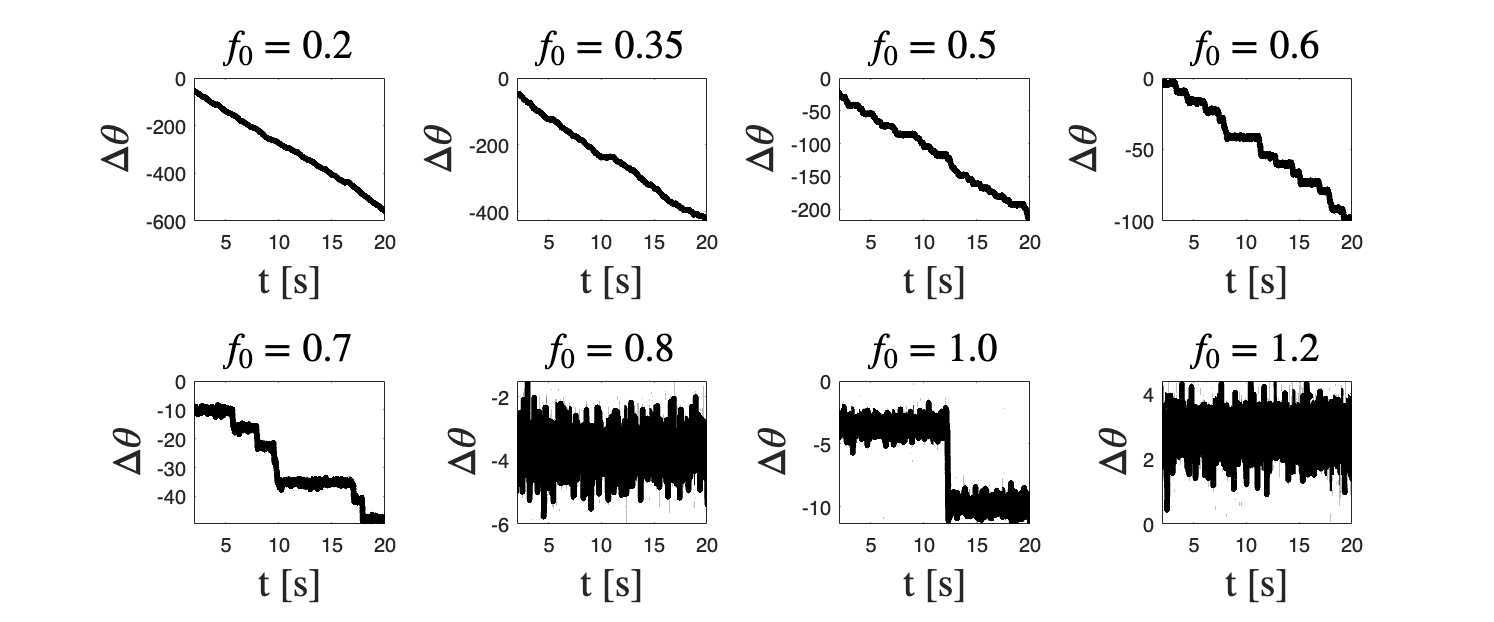

set(gcf,'Position',[100 100 1200 500])
tiledlayout(2,4);
nexttile
plot(t, phase_diff(:, 1), 'k', LineWidth=3);
xlim([2 t_max]);
xlabel('t [s]', 'Interpreter', 'latex', 'FontSize', 20);
ylabel('$\Delta \theta$', 'Interpreter', 'latex', 'FontSize', 20);
title('$f_0 = 0.2$', 'Interpreter', 'latex', 'FontSize', 20)
nexttile
plot(t, phase_diff(:, 2), 'k', LineWidth=3);
xlim([2 t_max]);
xlabel('t [s]', 'Interpreter', 'latex', 'FontSize', 20);
ylabel('$\Delta \theta$', 'Interpreter', 'latex', 'FontSize', 20);
title('$f_0 = 0.35$', 'Interpreter', 'latex', 'FontSize', 20)
nexttile
plot(t, phase_diff(:, 3), 'k', LineWidth=3);
xlim([2 t_max]);
xlabel('t [s]', 'Interpreter', 'latex', 'FontSize', 20);
ylabel('$\Delta \theta$', 'Interpreter', 'latex', 'FontSize', 20);
title('$f_0 = 0.5$', 'Interpreter', 'latex', 'FontSize', 20)
nexttile
plot(t, phase_diff(:, 4), 'k', LineWidth=3);
xlim([2 t_max]);
xlabel('t [s]', 'Interpreter', 'latex', 'FontSize', 20);
ylabel('$\Delta \theta$', 'Interpreter', 'latex', 'FontSize', 20);
title('$f_0 = 0.6$', 'Interpreter', 'latex', 'FontSize', 20)
nexttile
plot(t, phase_diff(:, 5), 'k', LineWidth=3);
xlim([2 t_max]);
xlabel('t [s]', 'Interpreter', 'latex', 'FontSize', 20);
ylabel('$\Delta \theta$', 'Interpreter', 'latex', 'FontSize', 20);
title('$f_0 = 0.7$', 'Interpreter', 'latex', 'FontSize', 20)
nexttile
plot(t, phase_diff(:, 6), 'k', LineWidth=3);
xlim([2 t_max]);
xlabel('t [s]', 'Interpreter', 'latex', 'FontSize', 20);
ylabel('$\Delta \theta$', 'Interpreter', 'latex', 'FontSize', 20);
title('$f_0 = 0.8$', 'Interpreter', 'latex', 'FontSize', 20)
nexttile
plot(t, phase_diff(:, 7), 'k', LineWidth=3);
xlim([2 t_max]);
xlabel('t [s]', 'Interpreter', 'latex', 'FontSize', 20);
ylabel('$\Delta \theta$', 'Interpreter', 'latex', 'FontSize', 20);
title('$f_0 = 1.0$', 'Interpreter', 'latex', 'FontSize', 20)
nexttile
plot(t, phase_diff(:, 8), 'k', LineWidth=3);
xlim([2 t_max]);
xlabel('t [s]', 'Interpreter', 'latex', 'FontSize', 20);
ylabel('$\Delta \theta$', 'Interpreter', 'latex', 'FontSize', 20);
title('$f_0 = 1.2$', 'Interpreter', 'latex', 'FontSize', 20)

*At noise = 250 rad/s*,

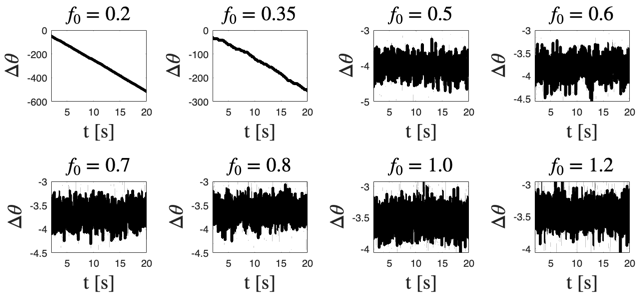

*At noise = 1000 rad/s*,

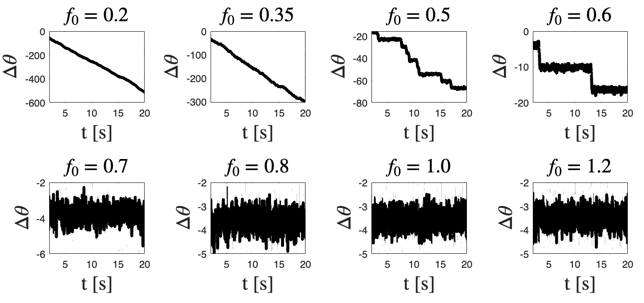

*At noise = 2500 rad/s*,

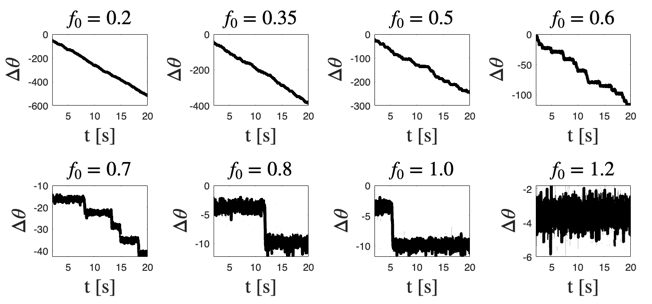

*At noise = 10000 rad/s*,

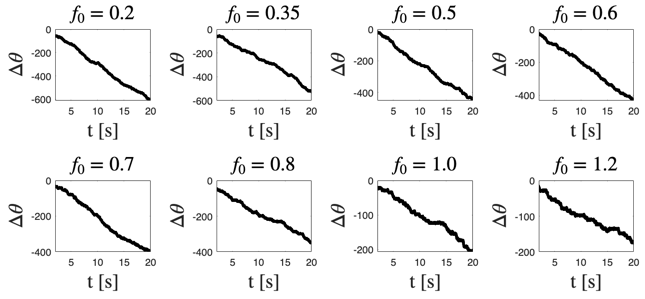

### Question 2

As the coupling strength is increased at a fixed noise amplitude value, initially there is not coupling. However, once coupling sets in, the slipping events become less frequent as coupling strength is increased further; consequently, the hair cell and the capillary remain coupled for longer intervals of time manifesting as longer plateaus on the plot.

Beyond a specific value of noise amplitude, the slipping events are no longer visible within the 20s time window being plotted, suggesting that the slipping events are occurring even less frequently.

The noise amplitude of **2500 rad/s** best matches figure 3 of Roongthumskul et al. (2013) in terms of the onset of coupling, while the range of phase differences are still quite different.

### Question 3

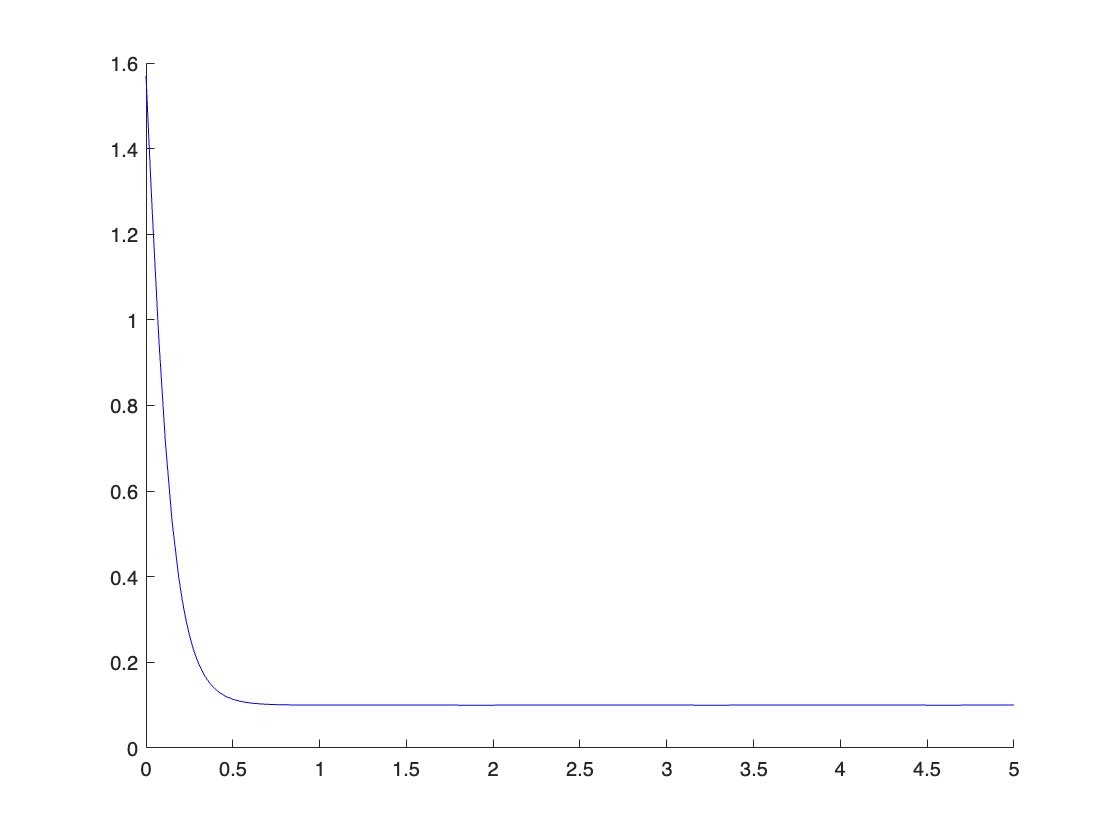

Tend = 5;

% parameters.
delOmega = 1;
eta = 5;
delTheta_start = pi/2;

% solve numerically.
[t_out, delTheta_out] = ode45(@(t, delTheta) delOmega - 2*eta*sin(delTheta), ...
    [0.0 Tend], delTheta_start);

% plot delTheta against time.
figure; hold on; zoom on;
plot(t_out, delTheta_out, 'b-');